clc;
clear;

%%%% getting path
addpath(genpath('xytheta'));

% load ('femm_output.mat')
% load ('test_revised05.09.mat')

% load('femm_out_sensor48_x[0,1]_y[2,10].mat')

load('femm_output.mat')


% a1a2a3a4 b1b2b3b4 c1c2c3c4
% too many figures
% 
% for m = x_index
%     for n = 1:1:4
%         f(n,m) = figure; %a
%         hold on;
%         legend("off")
%         legend("show",Location="best")
%         title(['x = ', num2str(x_position(1,m)),  '  sensor r=  ',num2str(sensor_r),' a',num2str(n)])
%         f(n+4,m) = figure; %b
%         hold on;
%         legend("off")
%         legend("show",Location="best")
%         title(['x = ', num2str(x_position(1,m)),  '  sensor r=  ',num2str(sensor_r),' b',num2str(n)])
%         f(n+8,m) = figure; %c
%         hold on;
%         legend("off")
%         legend("show",Location="best")
%         title(['x = ', num2str(x_position(1,m)),  '  sensor r=  ',num2str(sensor_r),' c',num2str(n)])
%     end
% end
% 
% for m = x_index
%     for n = y_index
%         figure(f(1,m));
%         plot(theta_r_in,a1(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
%         figure(f(2,m));
%         plot(theta_r_in,b1(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
%         figure(f(3,m));
%         plot(theta_r_in,c1(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
%         figure(f(4,m));
%         plot(theta_r_in,a2(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
%         figure(f(5,m));
%         plot(theta_r_in,b2(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
%         figure(f(6,m));
%         plot(theta_r_in,c2(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
%         figure(f(7,m));
%         plot(theta_r_in,a3(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
%         figure(f(8,m));
%         plot(theta_r_in,b3(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
%         figure(f(9,m));
%         plot(theta_r_in,c3(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
%         figure(f(10,m));
%         plot(theta_r_in,a4(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
%         figure(f(11,m));
%         plot(theta_r_in,b4(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
%         figure(f(12,m));
%         plot(theta_r_in,c4(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
%     end
% end

max_peak_flux = zeros(length(x_index),length(y_index));
min_peak_flux = zeros(length(x_index),length(y_index));


for x = x_index
    for y = y_index
        max_arr = [max(abs(a1(:,x,y))),max(abs(a2(:,x,y))),max(abs(a3(:,x,y))),max(abs(a4(:,x,y))), ...
            max(abs(b1(:,x,y))),max(abs(b2(:,x,y))),max(abs(b3(:,x,y))),max(abs(b4(:,x,y))) ...
            ,max(abs(c1(:,x,y))),max(abs(c2(:,x,y))),max(abs(c3(:,x,y))),max(abs(c4(:,x,y)))];
        max_peak_flux(x,y) = max(max_arr);
        min_peak_flux(x,y) = min(max_arr);
        diff = a1(:,x,y)-a2(:,x,y);
    end
end

max_peak_flux

max_peak_flux =     0.0307    0.0302    0.0297    0.0293    0.0293    0.0293    0.0298    0.0302    0.0307
    0.0302    0.0294    0.0289    0.0285    0.0284    0.0284    0.0290    0.0294    0.0303
    0.0298    0.0290    0.0282    0.0277    0.0275    0.0277    0.0281    0.0289    0.0297
    0.0293    0.0285    0.0277    0.0271    0.0267    0.0270    0.0277    0.0285    0.0293
    0.0293    0.0284    0.0276    0.0267    0.0259    0.0267    0.0275    0.0284    0.0293
    0.0293    0.0285    0.0277    0.0270    0.0267    0.0269    0.0277    0.0285    0.0293
    0.0297    0.0289    0.0282    0.0277    0.0276    0.0277    0.0282    0.0289    0.0297
    0.0303    0.0294    0.0290    0.0284    0.0284    0.0285    0.0289    0.0294    0.0302
    0.0307    0.0302    0.0298    0.0293    0.0294    0.0293    0.0297    0.0302    0.0307


min_peak_flux

min_peak_flux =     0.0219    0.0222    0.0226    0.0229    0.0229    0.0229    0.0226    0.0222    0.0219
    0.0223    0.0228    0.0232    0.0235    0.0236    0.0236    0.0232    0.0228    0.0222
    0.0226    0.0232    0.0238    0.0241    0.0243    0.0242    0.0238    0.0232    0.0225
    0.0229    0.0235    0.0242    0.0248    0.0251    0.0248    0.0242    0.0235    0.0229
    0.0229    0.0236    0.0244    0.0251    0.0258    0.0251    0.0244    0.0236    0.0229
    0.0229    0.0236    0.0241    0.0248    0.0251    0.0248    0.0242    0.0235    0.0229
    0.0226    0.0232    0.0238    0.0242    0.0243    0.0241    0.0238    0.0232    0.0225
    0.0222    0.0228    0.0231    0.0235    0.0236    0.0235    0.0232    0.0228    0.0222
    0.0218    0.0222    0.0226    0.0229    0.0229    0.0229    0.0226    0.0222    0.0219


dif_max_flux =max_peak_flux-min_peak_flux

dif_max_flux =     0.0088    0.0080    0.0071    0.0064    0.0064    0.0064    0.0072    0.0080    0.0088
    0.0080    0.0066    0.0057    0.0050    0.0049    0.0049    0.0058    0.0066    0.0080
    0.0072    0.0057    0.0044    0.0036    0.0032    0.0036    0.0044    0.0057    0.0071
    0.0064    0.0050    0.0035    0.0023    0.0016    0.0022    0.0035    0.0050    0.0064
    0.0064    0.0048    0.0032    0.0016    0.0001    0.0016    0.0032    0.0048    0.0064
    0.0064    0.0050    0.0036    0.0022    0.0016    0.0022    0.0035    0.0049    0.0065
    0.0071    0.0057    0.0044    0.0035    0.0033    0.0036    0.0044    0.0057    0.0072
    0.0081    0.0067    0.0058    0.0049    0.0048    0.0050    0.0058    0.0066    0.0080
    0.0088    0.0080    0.0073    0.0064    0.0065    0.0065    0.0072    0.0081    0.0088


max_flux = max(max(max_peak_flux))

max_flux = 0.0307

min_flux = min(min(min_peak_flux))

min_flux = 0.0218

dq = 2/3*[1 -0.5 -0.5;0 sqrt(3)/2 -sqrt(3)/2;1/2 1/2 1/2]

dq =     0.6667   -0.3333   -0.3333
         0    0.5774   -0.5774
    0.3333    0.3333    0.3333



alpha = zeros(4,length(theta_r_index),length(x_index),length(y_index));
beta = zeros(4,length(theta_r_index),length(x_index),length(y_index));
gamma = zeros(4,length(theta_r_index),length(x_index),length(y_index));
for(r = theta_r_index)
    for(x = x_index)
        for(y = y_index)
            alpha(1,r,x,y)=dq(1,:)*[a1(r,x,y);b1(r,x,y);c1(r,x,y)];
            alpha(2,r,x,y)=dq(1,:)*[a2(r,x,y);b2(r,x,y);c2(r,x,y)];
            alpha(3,r,x,y)=dq(1,:)*[a3(r,x,y);b3(r,x,y);c3(r,x,y)];
            alpha(4,r,x,y)=dq(1,:)*[a4(r,x,y);b4(r,x,y);c4(r,x,y)];
            beta(1,r,x,y)=dq(2,:)*[a1(r,x,y);b1(r,x,y);c1(r,x,y)];
            beta(2,r,x,y)=dq(2,:)*[a2(r,x,y);b2(r,x,y);c2(r,x,y)];
            beta(3,r,x,y)=dq(2,:)*[a3(r,x,y);b3(r,x,y);c3(r,x,y)];
            beta(4,r,x,y)=dq(2,:)*[a4(r,x,y);b4(r,x,y);c4(r,x,y)];
            gamma(1,r,x,y)=dq(3,:)*[a1(r,x,y);b1(r,x,y);c1(r,x,y)];
            gamma(2,r,x,y)=dq(3,:)*[a2(r,x,y);b2(r,x,y);c2(r,x,y)];
            gamma(3,r,x,y)=dq(3,:)*[a3(r,x,y);b3(r,x,y);c3(r,x,y)];
            gamma(4,r,x,y)=dq(3,:)*[a4(r,x,y);b4(r,x,y);c4(r,x,y)];
        end
    end
end

x12 = zeros(length(theta_r_index),length(x_index),length(y_index));
y12 = zeros(length(theta_r_index),length(x_index),length(y_index));
x34 = zeros(length(theta_r_index),length(x_index),length(y_index));
y34 = zeros(length(theta_r_index),length(x_index),length(y_index));

xhat = zeros(length(theta_r_index),length(x_index),length(y_index));
yhat = zeros(length(theta_r_index),length(x_index),length(y_index));

kg = 10100

kg = 10100


for(r = theta_r_index)
    for(x = x_index)
        for(y = y_index)
            x12(r,x,y) = alpha(1,r,x,y)*gamma(1,r,x,y)-alpha(2,r,x,y)*gamma(2,r,x,y);
            y12(r,x,y) = beta(1,r,x,y)*gamma(1,r,x,y)-beta(2,r,x,y)*gamma(2,r,x,y);
            x34(r,x,y) = cos(-pi/6)*(alpha(3,r,x,y)*gamma(3,r,x,y)-alpha(4,r,x,y)*gamma(4,r,x,y))-sin(-pi/6)*(beta(3,r,x,y)*gamma(3,r,x,y)-beta(4,r,x,y)*gamma(4,r,x,y));
            y34(r,x,y) = sin(-pi/6)*(alpha(3,r,x,y)*gamma(3,r,x,y)-alpha(4,r,x,y)*gamma(4,r,x,y))+cos(-pi/6)*(beta(3,r,x,y)*gamma(3,r,x,y)-beta(4,r,x,y)*gamma(4,r,x,y));

        end
    end
end


for(r = theta_r_index)
    for(x = x_index)
        for(y = y_index)
            xhat(r,x,y) = kg*(x12(r,x,y)+x34(r,x,y));
            yhat(r,x,y) = -kg*(y12(r,x,y)+y34(r,x,y));
        end
    end
end

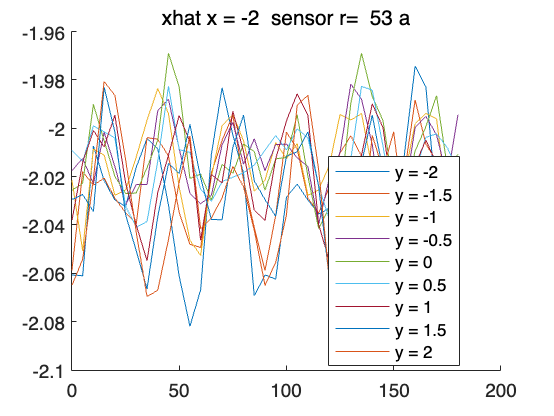

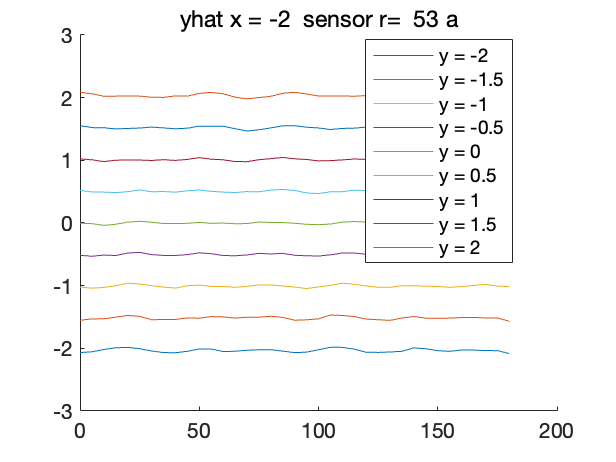

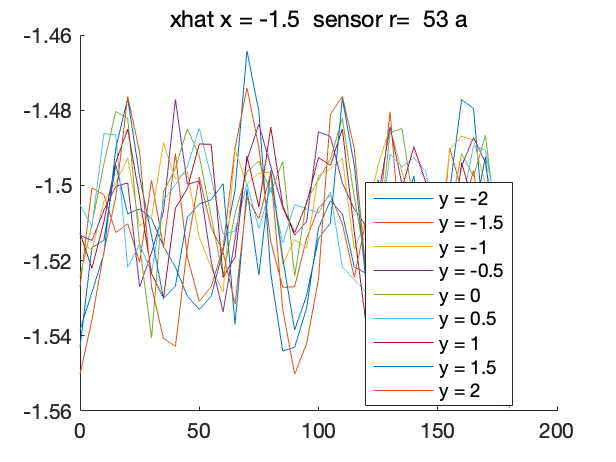

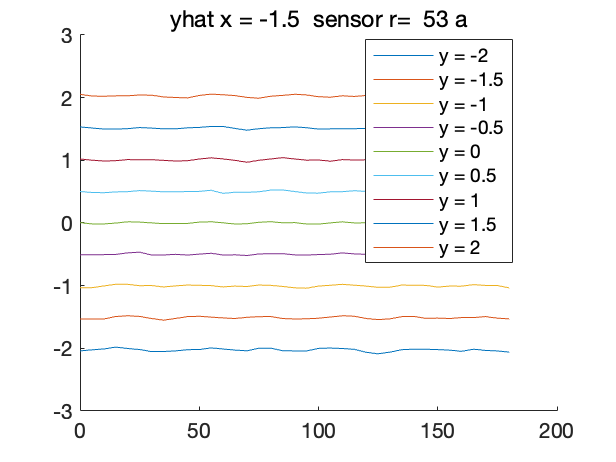

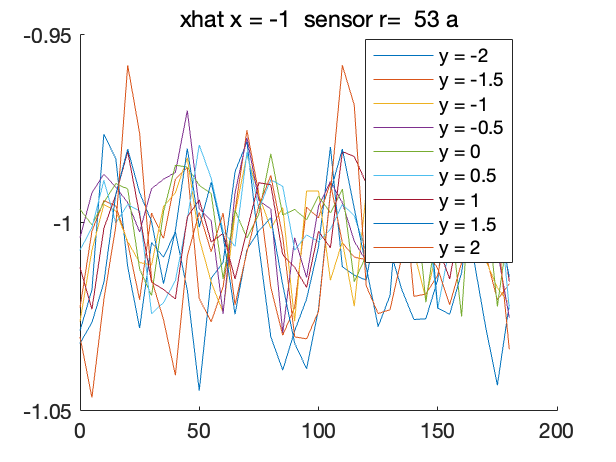

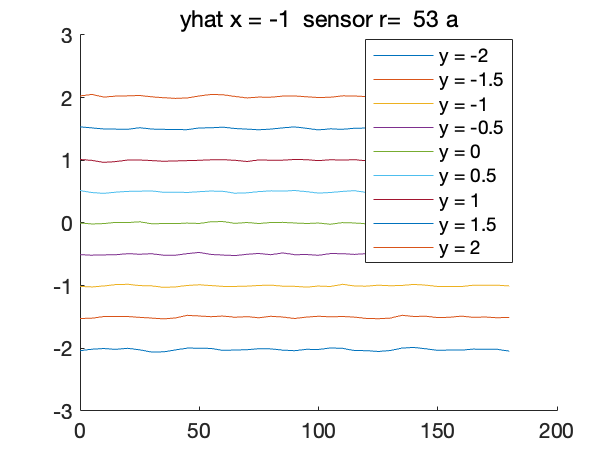

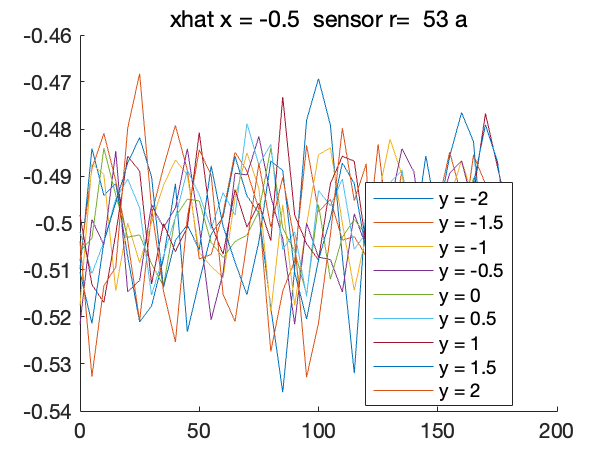

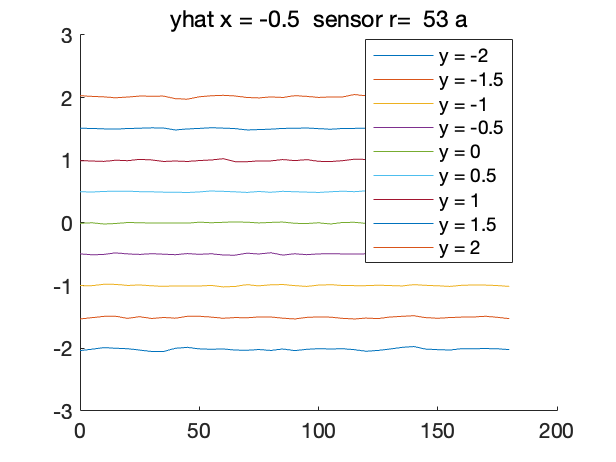

f2 = zeros(length(x_index),2);

for m = x_index
        f2(m,1) = figure; %a
        hold on;
        legend("off")
        legend("show",Location="best")
        title(['xhat ','x = ', num2str(x_position(1,m)),  '  sensor r=  ',num2str(sensor_r),' a'])
        f2(m,2) = figure;
        hold on;
        legend("off")
        legend("show",Location="best")
        title(['yhat ','x = ', num2str(x_position(1,m)),  '  sensor r=  ',num2str(sensor_r),' a'])
    for n = y_index
        figure(f2(m,1));
        plot(theta_r_in,xhat(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
        figure(f2(m,2));
        plot(theta_r_in,yhat(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
    end
end

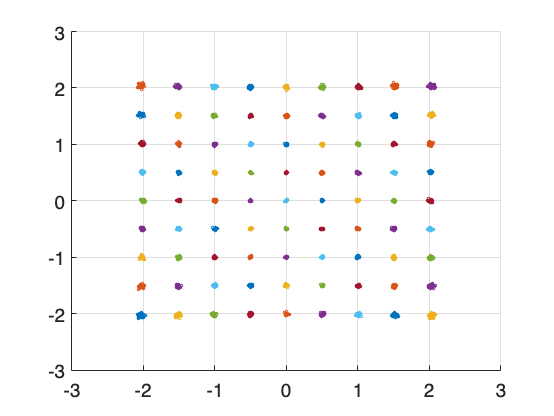

hi = figure;
hold on;
grid on;
for m = x_index
    for n = y_index
        scatter(xhat(:,m,n),yhat(:,m,n),2)
    end
end